# Assignment 2 Cagin Sari

# MATLAB Instruction - Far-field evaluation

## Figure Defaults

set(0,'DefaultLineLineWidth',2)
set(0,'defaultAxesFontSize',18)
set(0,'defaultAxesLinewidth',2)
set(0,'defaultfigureposition',[100 100 600 600])

# **Farfield evaluated using SGF**

## **Theory**

The far field radiated by an electric current can be evaluated asmptotically in spectral domain as follows:

where $\left(x^{\prime } ,y^{\prime } ,z^{\prime } \right)$is the source position while $\left(x,y,z\right)$ is the observation position, $k_{\textrm{xs}} =k\sin \theta \;\cos \phi ,k_{\textrm{ys}} =k\sin \theta \;\sin \phi ,k_{\textrm{zs}} =k\cos \theta \;$rerepresent the dominant plane wave,$\overrightarrow{J} \left(k_{\textrm{xs}} ,k_{\textrm{ys}} \right)$ is the FT of the current distribution, and ${\tilde{G} }^{\textrm{ej}}$ is the dyadic SGF for electric currents:

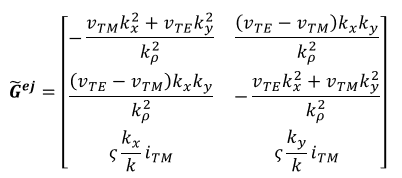

where $v_{\textrm{TM}} ,v_{\textrm{TE}} ,i_{\textrm{TM}} ,i_{\textrm{TE}}$ are obtained from the transmission line solution of the stratification.

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

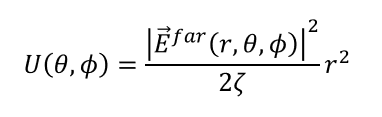

and $P_{\textrm{rad}}$ is the total radiated power:

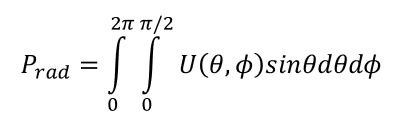

Note that here we only consider the power integrated over the upper hemisphere. For antennas with symmetric patterns such as a free-space dipole, we can simply x2 outside the function. 

## MATLAB Implementation

To evaluate the farfield radiated by a current, we should follow the listed steps:

**(1)** Solve the transmission line model of the straitification. **(2)** Calculate the dyadic SGF. **(3)** Obtain the FT of the current distribution. **(4)** Use Eq.1 to calculate the farfield. **(5) **Evaluate the directivity and radiated power from the farfield.

The above steps are applicable for any source so it would be convenient to build separate routines for these steps, and then reuse them for different applications. Today you should learn how to build these routines for different stratifications:

**(1)** [v_TM, v_TE, i_TM, i_TE] = **txline_xxxx**(k0, er, h, kro, z);

**(2) **ej_SGF = **EJ_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE);

**(3)** Jx = **FTCurrent**(k, er, kx, ky, l, w)

**(4)** [Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx)

**(5)** [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q1 (3 points): Grounded Dielectric Slab

Evaluate the far field radiated by an electric dipole with $L=W=0\ldotp 25$ mm placed on the top of a grounded slab with thickness $h=0\ldotp 8$ mm and $\varepsilon_r =12$.

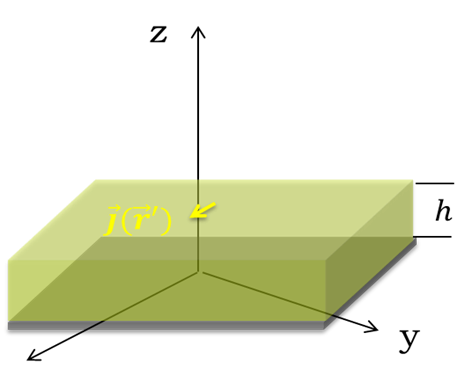

### 1. Far field along the main planes at 28 GHz

Calculate the far field in $\phi =0^{\circ \;} /{90}^{\circ \;}$ planes by considering the radiation in spectral domain.

**Step 1:  Solution of the equivalent transmission line**

The stratification can be modelled as a transmission line, where the current generator represents the electric current:

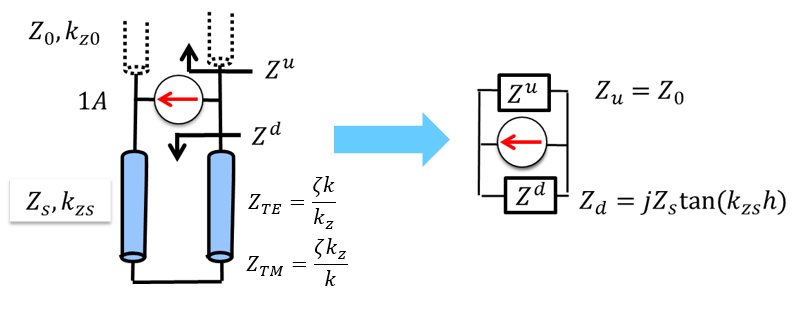

After solving the circuit, one can obtain the voltage and current solutions in the air:

    Write a routine to calculate TE/TM solutions: [vtm, vte, itm, ite] = **txline_groundslab**(k0, er, h, krho, z)

% Constant
clc
clear all
close all

L  = 0.25e-3;
W  = 0.25e-3;
h  = 0.8e-3;
er = 12;
f  = 28e9;
lambda = 3e8 / f;
k0 = 2 * pi / lambda;
k1 = k0.*sqrt(er) ;
keq = (k0+k1)./2 ;

% FF parameters
R_FF = 1;
phi  = (eps:2:360) * pi / 180;

theta = linspace(eps, 89.9, 90) * pi / 180;
dth = theta(2) - theta(1);
dph = phi(2) - phi(1);
[TH, PH] = meshgrid(theta, phi);

KX   = k0 * sin(TH) .* cos(PH);
KY   = k0 * sin(TH) .* sin(PH);
KZ   = k0 * cos(TH);
KRHO = sqrt(KX.^2 + KY.^2);
Z    = R_FF * cos(TH);

% calculate voltages and currents
% txline_groundslab(k0, er, h, KRHO, Z);
zeta0 = 120*pi ;
% [vtm, vte, itm, ite,kz1] = txline_GroundSlab(k0,zeta0,er,Z,h,KRHO,f) ;
%  figure


**Step 2:  Calculate the Dyadic SGF**

Build the Dyad for electric current ${\tilde{G} }^{\textrm{ej}}$: ej_SGF = **EJ_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE, flag);

% calculate Green's function
[vtm, vte, itm, ite, kzs ,kz0] = txline_GroundSlab(k0,zeta0,er,Z,h,KRHO,f) ;
ej_sgf = SpectralGFej(k0,k1,er,KX,KY,vtm,vte,itm,ite,zeta0,KRHO,Z,h) ;
Gxx = ej_sgf(:,:,1,1) ;
Gyx = ej_sgf(:,:,2,1) ;
Gzx = ej_sgf(:,:,3,1) ;
% plot(KX(1,:), 20*log10(abs(vte(1,:))))

**Step 3:  Calculate the FT of the current distribution**

For dipole antennas, we can approximate the spatial current distribution using the current distribution along an open circuited transmission line. This distribution can be expressed in general as follows:

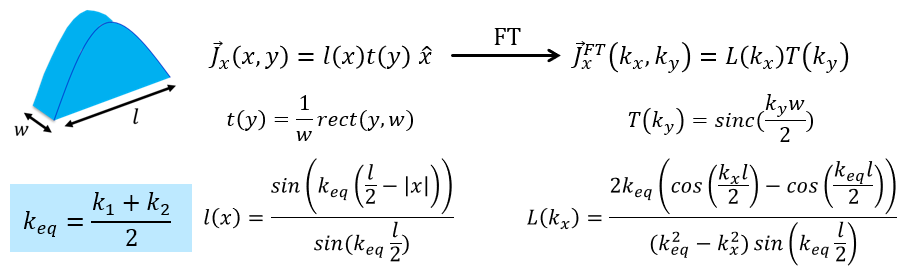

Write a routine to calculate the FT of currents: Jx = **FTCurrent**(k, er, kx, ky, l, w, flag_current)

% calculate FT of current distribution
Jx = FTCurrent(keq, KX, KY, L, W);

**Step 4:  Evaluate far fields **

 

Calculate the FF in Eth and Eph and plot the total field: 

[Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx);

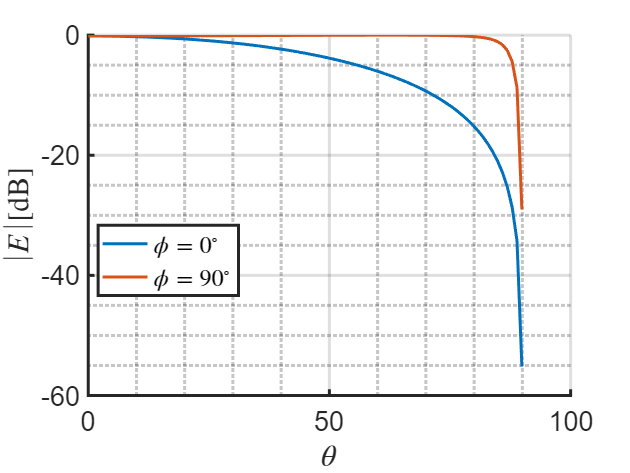

% calculate far field
[Eth, Eph] = farfield(TH, PH, KZ, Gxx, Gyx, Gzx, Jx,Z,1,h,k0);
Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
% Etot(isnan(Etot)) = 0 ;
% Etot(isinf(Etot)) = 0 ;

figure 
hold on
% a(isnan(a)) = 0 ;
% a(isinf(a)) = 0 ;
plot(rad2deg(theta), 20*log10(Etot(1,:))-20*log10(max(max(Etot(:,:) ) ) ),'DisplayName','$\phi = 0^\circ$' ) ;
plot(rad2deg(theta), 20*log10(Etot(45,:))-20*log10(max(max(Etot(:,:) ) ) ) ,'DisplayName','$\phi = 90^\circ$' ) ; grid on; grid minor;
legend('Location','best','Interpreter','latex');
hold off
xlabel('$\theta$','Interpreter','latex');
ylabel('$\left|E\right|$[dB]','Interpreter','latex')

The plot above demonstrates the farfield radiated from elementary electric current placed on top of a grounded slab. The electric far is constant until in the $\phi = 90^\circ

$ until $\theta = 90^\circ
$(because of the ground plane field goes to zero), but it is not constant in $\phi = 0^\circ
$. 

### 2. Plot the radiated power from 10 GHz to 40 GHz normalized to the radiated power that the same dipole will radiate in free space. 

Calculate the FF as a function of frequency for both stratified and free-space cases. Radiated power can be obtained by integrating the FF pattern: [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r);

Dipole in free space: 2*, outside the function.

Dipole in grounded slab:, radiation exists only on the upper hemisphere.

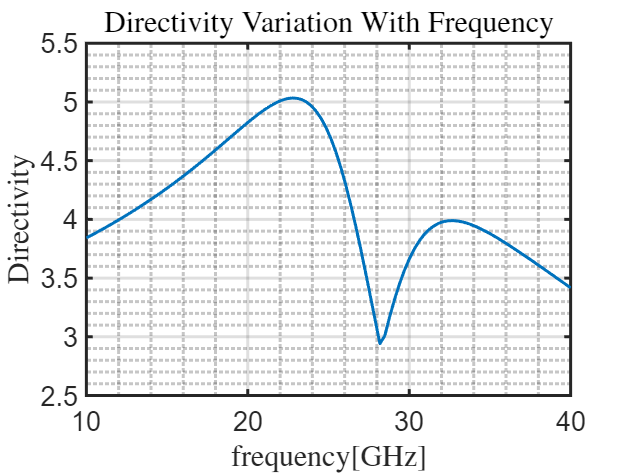

% Power radiated
freq = linspace(10,40,100) .*1e9 ;
for ff = 1:length(freq) 

    lambda = 3e8 / freq(ff);
    k0 = 2 * pi / lambda;
    k1 = k0.*sqrt(er) ;
    keq = (k0+k1)./2 ;

    KX   = k0 * sin(TH) .* cos(PH);
    KY   = k0 * sin(TH) .* sin(PH);
    KZ   = k0 * cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);

    % Radiation from Grounded Slab
    [vtm, vte, itm, ite, kzs ,kz0] = txline_GroundSlab(k0,zeta0,er,Z,h,KRHO,freq(ff)) ;
    ej_sgf = SpectralGFej(k0,k1,er,KX,KY,vtm,vte,itm,ite,zeta0,KRHO,Z,h) ;
    Gxx = ej_sgf(:,:,1,1) ;
    Gyx = ej_sgf(:,:,2,1) ;
    Gzx = ej_sgf(:,:,3,1) ;
    [Eth, Eph] = farfield(TH, PH, KZ, Gxx, Gyx, Gzx, Jx,Z,1,h,k0) ;
    Etot = sqrt(abs(Eth).^2 + abs(Eph).^2) ;
    [Dir, prad(ff)] = Direc(Etot, TH, dth, dph, R_FF);
    D(ff) = Dir(1,1) ;

    % calculate voltages and currents
    ej_SGF = EJ_SGF(1, k0, KX, KY);
    Gxx = ej_SGF(:,:,1,1);
    Gyx = ej_SGF(:,:,2,1);
    Gzx = ej_SGF(:,:,3,1);

    % Radiation from free space dipole
    [Eth, Eph] = farfield(TH, PH, KZ, Gxx, Gyx, Gzx, Jx,0,1,0,k0);
    E_tot_element = sqrt(abs(Eth).^2 + abs(Eph).^2);
    [~, Pradiated_element(ff)] = Direc(E_tot_element, TH, dth, dph, 1); 

end
figure 
plot(freq/1e9, abs(D))
xlabel('frequency[GHz]','Interpreter','latex') ;
ylabel('Directivity','Interpreter','latex');
title('Directivity Variation With Frequency ','Interpreter','latex') ; grid on ;grid minor;

At the frequency $28.18GHz
$ the directivity decreases by a factor 1.7. This is probably the cutoff frequency of surface wave mode, the power transferred to the surface wave mode reduces the directivity of the far-field.

### 3. For which thickness is this normalized power of the dipole the highest? Why?

Find this value in **2**, and represent it in terms of wavelength in dielectric.

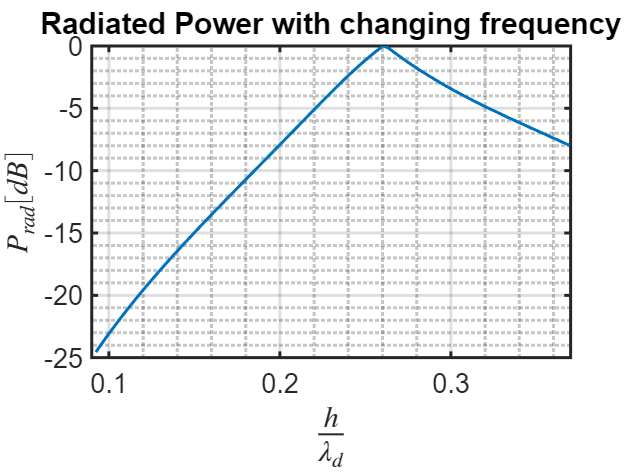

% h_opt = 
% Power radiated
lambda0 = 3e8./freq ;
lambdas = lambda0 ./ sqrt(er) ;
h_lambda = h./lambdas ;
figure
plot(h_lambda,10*log10(prad)-10*log10(max(prad)) );
xlim([0.09 0.37]) ;
xlabel('$\frac{h}{\lambda_d}$','Interpreter','latex');
ylabel('$P_{rad}[dB]$','Interpreter','latex');
title('Radiated Power with changing frequency'); grid on;grid minor ;

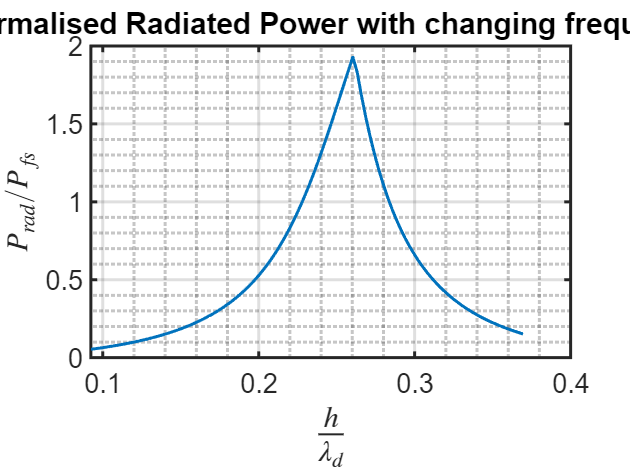

figure
plot(h_lambda,abs(prad)./abs(Pradiated_element) .*0.5 ,'DisplayName','Radiated Power');
xlabel('$\frac{h}{\lambda_d}$','Interpreter','latex');
ylabel('$P_{rad}/P_{fs}$','Interpreter','latex');
title('Normalised Radiated Power with changing frequency'); grid on;grid minor ;

The normalised radiated power is maximum at $0.26 \frac{h}{\lambda_s}$, the reason is the reflected power from the ground plane is matched to the free space impedance, resulting in maximum power transfer.

# Q2 (4 points): Standard Leaky-wave antenna

Calculate the far field radiated by a magnetic current in the presence of the stratification shown in the figure. Consider $h=5\ldotp 4$mm, $h_s =0\ldotp 77$mm, $\varepsilon_r =12$, and a half-wavelength magnetic dipole with $W=\lambda /20$.

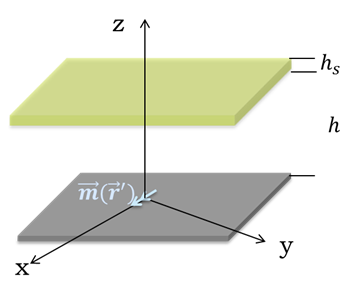

### 1. Far field along main planes at 26**, 28**, and 30 GHz.

Calculate the far field in $\phi =0^{\circ \;} /{90}^{\circ \;}$ planes at **three** frequency points.

**Step 1:  Solution of the equivalent transmission line**

 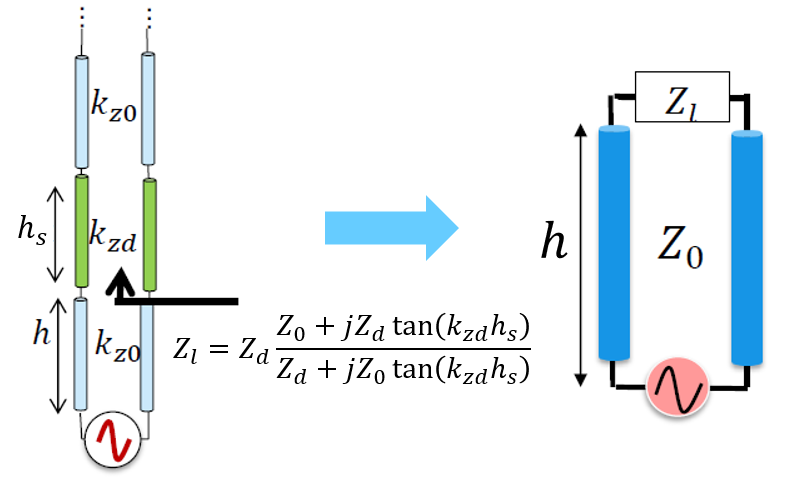

Write a routine to calculate TE/TM solutions: [vtm, vte, itm, ite] = **txline_superstrate**(k0, er, h, hs, krho, z)

% Constant
clc
clear all
close all

er = 12;
f  = 28e9;
lambda = 3e8 / f;
k0 = 2 * pi / lambda;
k1 = k0.*sqrt(er) ;

% FF parameters
R_FF = 1;
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 90, 303) * pi / 180;
[TH, PH] = meshgrid(theta, phi);

% calculate voltages and currents
% txline_groundslab(k0, er, h, KRHO, Z);
zeta0 = 120*pi ;
% [vtm, vte, itm, ite,kz1] = txline_GroundSlab(k0,zeta0,er,Z,h,KRHO,f) ;
%  figure
hs = 0.77e-3 ;
h = 5.4e-3 ;
er = 12 ;
freq = [26,28,30]*1e9 ;



**Step 2:  Calculate the Dyadic SGF**

Build the Dyad for magnetic current ${\tilde{G} }^{\textrm{em}}$: em_SGF = **EM_SGF**(er, k, kx, ky, v_TM, v_TE, i_TM, i_TE, flag);

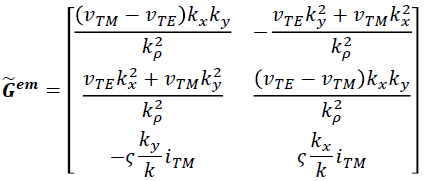

for ii = 1:length(freq)

    lambda = 3e8./freq(ii) ;
    k0 = 2.*pi./lambda ;
    W = lambda ./ 20 ;
    L = lambda./2 ;

    KX   = k0 .* sin(TH) .* cos(PH);
    KY   = k0 .* sin(TH) .* sin(PH);
    KZ   = k0 .* cos(TH);
    KRHO = sqrt(KX.^2 + KY.^2);
    Z    = R_FF * cos(TH);

    % calculate voltages and currents
    [vte, vtm, ~, itm, ks,kz0] = trxline_Superstrate(k0, zeta0, er, h, hs, KRHO, 'Layer3' ,Z, freq(ii)) ;
    % calculate Green's function
    [em_sgf] = SpectralGFem(k0,ks,er,KX,KY,vtm,vte,itm,'Layer2',zeta0,KRHO) ;
    Gxx = em_sgf(:,:,1,1) ;
    Gyx = em_sgf(:,:,2,1) ;
    Gzx = em_sgf(:,:,3,1) ;
    % calculate FT of current distribution
    Mx = FTCurrent( k0, KX, KY, L, W ) ;
    % calculate far field
    [Eth, Eph] = farfield( TH, PH, KZ, Gxx, Gyx, Gzx, Mx, Z,R_FF,0,k0) ;
    Etot(:,:,ii) = sqrt( abs(Eth).^2 +abs(Eph).^2 ) ;

    ej_SGF = EJ_SGF(1, k0, KX, KY);
    Gxx = ej_SGF(:,:,1,1);
    Gyx = ej_SGF(:,:,2,1);
    Gzx = ej_SGF(:,:,3,1);

    [Ethelem, Ephelem] = farfield( TH, PH, KZ, Gxx, Gyx, Gzx, Mx, Z,R_FF,0,k0) ;
    Etotelem(:,:,ii) = sqrt( abs(Ethelem).^2 +abs(Ephelem).^2 ) ;

end

**Step 3:  Calculate the FT of the current distribution**

Same routine as the previous case.

**Step 4:  Evaluate far fields **

Same routine as the previous case. In fact, you can find $h=\frac{\lambda_{0\;} }{2}$, $h_s =\frac{\lambda_0 }{4\sqrt{\;\varepsilon_r }}$ are the resonant conditions.

### 2. Compare the far field with that of the magnetic current radiating in free space at 28 GHz.

Solve a new transmission line for free space case.

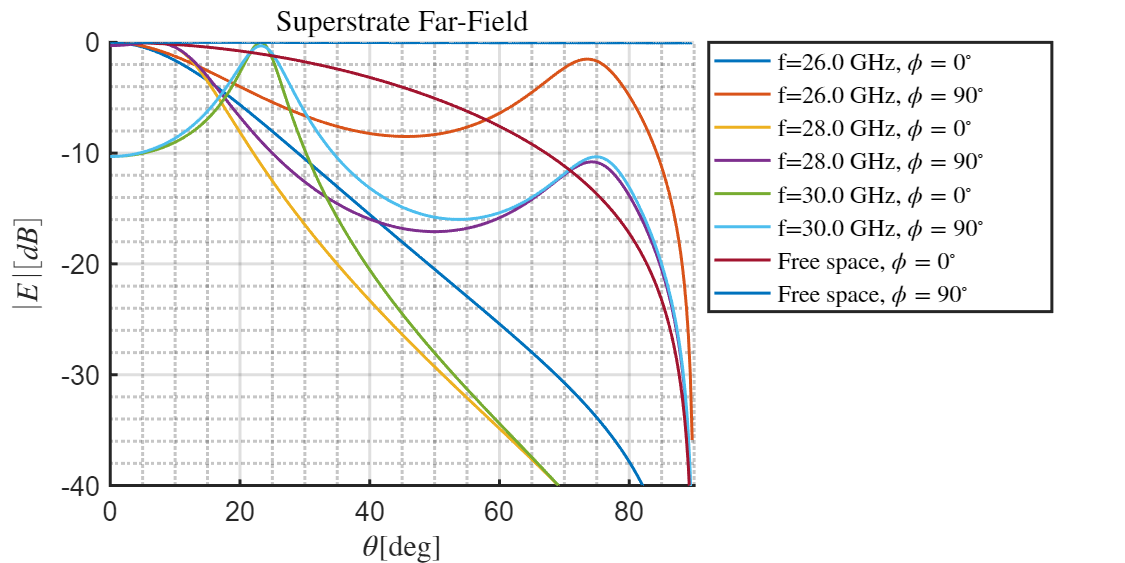

% FF in FS
figure
hold on
for ii =1:length(freq)
    plot(rad2deg(theta), 20*log10(abs(Etot(1,:,ii)))-20*log10( abs(max(max(max(Etot(1,:,ii) ) ) ) ) ),'DisplayName',sprintf('f=%.1f GHz, $\\phi=0^\\circ$',freq(ii)./1e9 ) ) ;
    plot(rad2deg(theta), 20*log10(abs(Etot(round(length(phi)./4),:,ii)))-20*log10(abs(max(max(max(Etot(1,:,ii) ) ) ) ) ),'DisplayName',sprintf('f=%.1f GHz, $\\phi=90^\\circ$',freq(ii)./1e9 ) ) ;
end
ii=2;
plot(rad2deg(theta), 20*log10(abs(Etotelem(1,:,ii)))-20*log10( abs(max(max(max(Etotelem(1,:,ii) ) ) ) ) ),'DisplayName',sprintf('Free space, $\\phi=0^\\circ$',freq(ii)./1e9 ) ) ;
plot(rad2deg(theta), 20*log10(abs(Etotelem(round(length(phi)./4),:,ii)))-20*log10(abs(max(max(max(Etotelem(1,:,ii) ) ) ) ) ),'DisplayName',sprintf('Free space, $\\phi=90^\\circ$',freq(ii)./1e9 ) ) ;
legend('-DynamicLegend');
legend('Interpreter','latex');
ylim([-40 0]);
xlim([0 90]) ;
title('Superstrate Far-Field','Interpreter','latex')
xlabel('$\theta$[deg]','Interpreter','latex');
ylabel('$\left|E\right|[dB]$ ','Interpreter','latex') ;
legend('Location','bestoutside') ; grid on ; grid minor; 
set(0,'defaultfigureposition',[100 100 1000 400])
hold off

In this stratification type leaky waves are supported and, it can be seen that it shapes the beam in a way that increases the directivity, by decreasing the beamwidth. Comparing to the field radiated by the same dipole in free space one can see that

free space dipole has very wide beamwidth, the stratification being used highly increases the directivity of the antenna.

### 3. Directivity$\left(\textrm{at}\;\theta =0^{\circ \;} \right)$ as a function of relative permittivity at 28 GHz. Consider a variation $\left(\varepsilon_r \right)$ from 1 to 25,  with the dielectric thickness $h_s =\frac{\lambda_0 }{4\sqrt{\;\varepsilon_r }}$. 

Calculate the directivity at $\theta =0^{\circ \;}$ as a function of $\varepsilon_r$. 

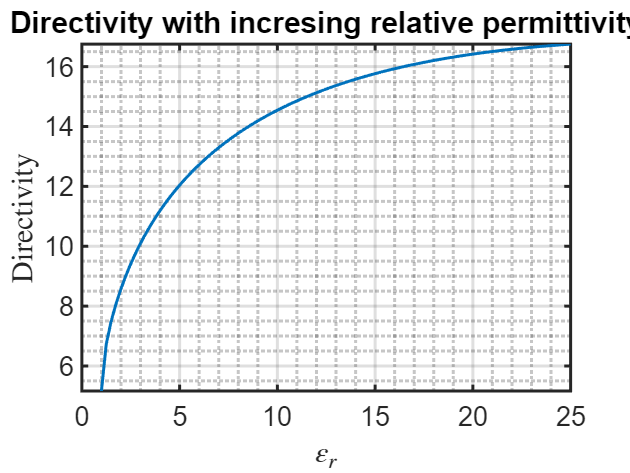

% Constant
clc
clear all
close all

% FF parameters
freq = 28e9 ;
R_FF = 1;
phi  = (eps:2:360) * pi / 180;
h = 5.4e-3 ;
lambda = 3e8 / freq;
k0 = 2 * pi / lambda;

theta = linspace(eps, 89.9, 303) * pi / 180;
dth = theta(2) - theta(1);
dph = phi(2) - phi(1);
[TH, PH] = meshgrid(theta, phi);
zeta0 = 120*pi ;
er = linspace(1,25,100) ;
W = lambda ./ 20 ; 
L = lambda./2 ;

[KX,KY,KZ] =PropVectors(k0,TH,PH) ;
KRHO = sqrt(KX.^2 + KY.^2);
Z    = R_FF * cos(TH);

for ff = 1:length(er) 

    
    hs = lambda./(4 .*sqrt(er(ff) ) ) ;
    k1 = k0.*sqrt(er(ff)) ;
    keq = (k0+k0)./2 ;

    [vte, vtm, ~, itm, ks,kz0] = trxline_Superstrate(k0, zeta0, er(ff), h, hs, KRHO, 'Layer3' ,Z, freq) ;
    % calculate Green's function
    [em_sgf] = SpectralGFem(k0,ks,er(ff),KX,KY,vtm,vte,itm,'Layer2',zeta0,KRHO) ;
    Gxx = em_sgf(:,:,1,1) ;
    Gyx = em_sgf(:,:,2,1) ;
    Gzx = em_sgf(:,:,3,1) ;
    % calculate FT of current distribution
    Mx = FTCurrent( keq, KX, KY, L, W ) ;
    % calculate far field
    [Eth, Eph] = farfield( TH, PH, KZ, Gxx, Gyx, Gzx, Mx, Z,R_FF,h,k0) ;
    Etot(:,:,ff) = sqrt( abs(Eth).^2 +abs(Eph).^2 ) ;
    Etot(isnan(Etot(:,:,ff) ) ) = 0 ;
    [Dir, prad(ff)] = Direc(Etot(:,:,ff), TH, dth, dph, R_FF);
    D(ff) = Dir(1,1) ;

end
figure 
plot(er, 10*log10(abs(D))) ;
xlabel('$\varepsilon_r$','Interpreter','latex');
ylabel('Directivity','Interpreter','latex');
title('Directivity with incresing relative permittivity')
grid on; grid minor ;

With increasing permittivity the directivity increases, this is because the higher the permittivity the smaller the angle of transmission $\theta_t$ according to Snell's law therefore the directivity increases.

# Q3 (3 points): Resonant Leaky-wave antenna

Calculate the far field radiated by a magnetic current into an infinite medium in the presence of the stratification shown in the figure. Consider $h=5\ldotp 4$ mm,  a frequency of $28$ GHz, and a half-wavelength magnetic dipole with $W=\lambda /20$. 

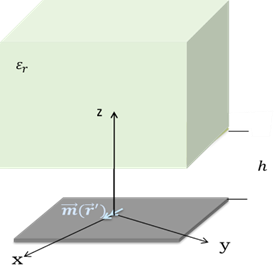

### 1. Far field along main planes when $\varepsilon_r =12$.

Note that the far field is now radiated inside a dielectric medium. The spectral parameters should be modified:


$$k_{\textrm{xs}} =k_d \;\sin \theta \;\cos \phi ,k_{\textrm{ys}} =k_d \;\sin \theta \;\sin \phi ,k_{\textrm{zs}} =k_d \;\cos \theta \;$$


**Step 1:  Solution of the equivalent  transmission line**

**Step 2:  Calculate the Dyadic SGF**

**Step 3:  Calculate the FT of the current distribution**

% calculate Green's function
% [Gxx, Gyx, Gzx] = EM_SGF(k0, er, KX, KY, vtm, vte, itm, ite);
% calculate FT of current distribution
% Mx = FTCurrent(k0, 1, KX, KY, L, W);
% calculate far field
% [Eth, Eph] = farfield(kd, R_FF, TH, PH, Gxx, Gyx, Gzx, Mx, KZ, Z);

**Step 4:  Evaluate far fields **

**Constants**

% Constant
clc
clear all
close all

% FF parameters
R_FF = 1;
phi  = (eps:2:360) * pi / 180;
theta = linspace(eps, 89.9, 303) * pi / 180;
dth = theta(2) - theta(1);
dph = phi(2) - phi(1);
[TH, PH] = meshgrid(theta, phi);

zeta0 = 120*pi ;
h = 5.4e-3 ;
er = 12 ;
freq = 28e9 ;
lambda = 3e8./freq ;
k0 = 2.*pi./lambda ;
k1 = k0 .*sqrt(er) ;
keq = (k0+k0)./2 ;
W = lambda ./ 20 ; 
L = lambda./2 ;

## Evaluate Far-field 

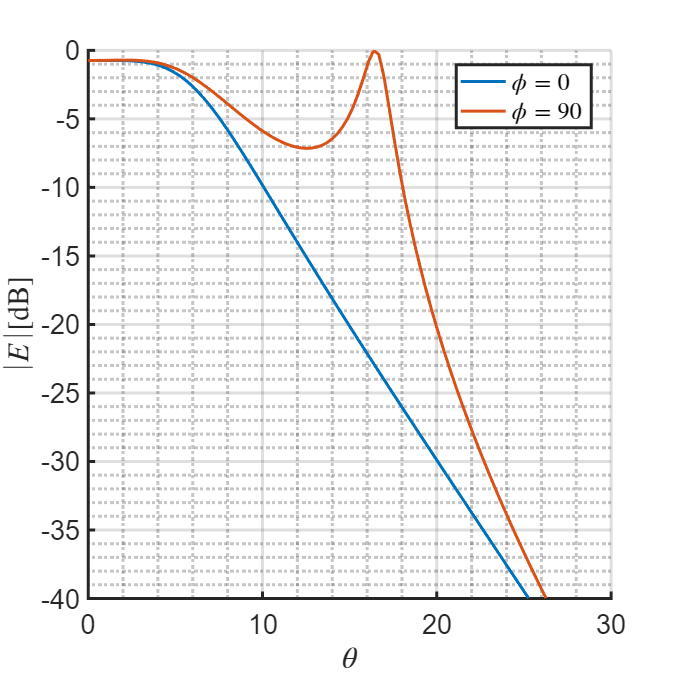

[KX,KY,KZ] = PropVectors(k1,TH,PH) ;
KRHO = sqrt(KX.^2 + KY.^2);
Z    = R_FF * cos(TH);

% calculate voltages and currents
[vte,vtm,ite,itm,~] = trxline_semi_inf_Superstrate(k0,er,h,KRHO,Z,'Layer2') ;
% [vte1, ite1, vtm1, itm1] = stratified_media(k0, KRHO, Z, 'SemiInfiniteSuperstrate', h, er);
% calculate Green's function
[em_sgf] = SpectralGFem(k0,k1,er,KX,KY,vtm,vte,itm,'Layer1',zeta0,KRHO) ;
Gxx = em_sgf(:,:,1,1) ;
Gyx = em_sgf(:,:,2,1) ;
Gzx = em_sgf(:,:,3,1) ;
% calculate FT of current distribution
Mx = FTCurrent( keq, KX, KY, L, W ) ;
% calculate far field
[Eth, Eph] = farfield( TH, PH, KZ, Gxx, Gyx, Gzx, Mx, Z,R_FF,h,k1) ;
Etot = sqrt( abs(Eth).^2 +abs(Eph).^2 ) ;
Etot(isnan(Etot(:,:))) = 0 ;

figure
hold on
plot(rad2deg(theta) ,20*log10(abs(Etot(1,:)) )- 20*log10(max(max( ( abs( Etot(:,:) ) ) ) ) ) ,'DisplayName','$\phi=0$')
plot(rad2deg(theta) ,20*log10(abs(Etot(45,:)) ) - 20*log10(max(max( ( abs( Etot(:,:) ) ) ) ) ),'DisplayName','$\phi=90$' )
ylim([-40 0]) ;
xlim([0 30]) ;
xlabel('$\theta$','Interpreter','latex');
ylabel('$\left|E\right|$[dB]','Interpreter','latex');grid on; grid minor;
legend('Location','best','Interpreter','latex')
hold off

### 2. Directivity$\left(\textrm{at}\;\theta =0^{\circ \;} \right)$ as a function of relative permittivity at 28 GHz. Consider a variation $\left(\varepsilon_r \right)$ from 1 to 25. 

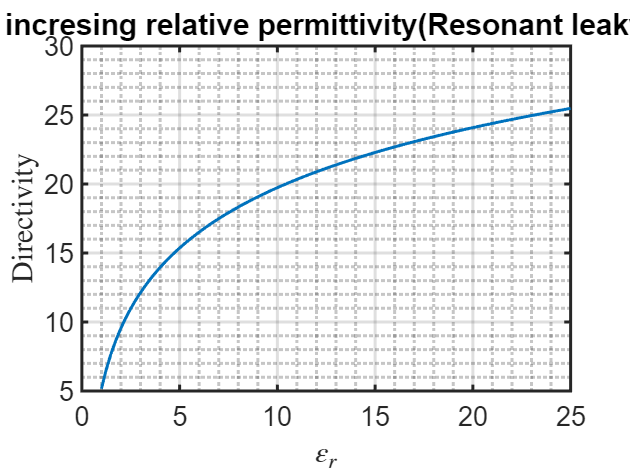

% Constant
clc
clear all
close all

% FF parameters
freq = 28e9 ;
R_FF = 1;
phi  = (eps:2:360) * pi / 180;
h = 5.4e-3 ;
lambda = 3e8 / freq;
k0 = 2 * pi / lambda;

theta = linspace(eps, 89.9, 303) * pi / 180;
dth = theta(2) - theta(1);
dph = phi(2) - phi(1);
[TH, PH] = meshgrid(theta, phi);
zeta0 = 120*pi ;
er = linspace(1,25,100) ;
W = lambda ./ 20 ; 
L = lambda./2 ;



for ff = 1:length(er)

    hs = lambda./(4 .*sqrt(er(ff) ) ) ;
    k1 = k0.*sqrt(er(ff)) ;
    keq = (k0+k0)./2 ;

    [KX,KY,KZ] =PropVectors(k1,TH,PH) ;
    KRHO = sqrt(KX.^2 + KY.^2);
    Z    = R_FF * cos(TH);

    [vte,vtm,~,itm,ks] = trxline_semi_inf_Superstrate(k0, er(ff), h, KRHO ,Z, 'Layer2') ;
    % calculate Green's function
    [em_sgf] = SpectralGFem(k0,ks,er(ff),KX,KY,vtm,vte,itm,'Layer1',zeta0,KRHO) ;
    Gxx = em_sgf(:,:,1,1) ;
    Gyx = em_sgf(:,:,2,1) ;
    Gzx = em_sgf(:,:,3,1) ;
    % calculate FT of current distribution
    Mx = FTCurrent( keq, KX, KY, L, W ) ;
    % calculate far field
    [Eth, Eph] = farfield( TH, PH, KZ, Gxx, Gyx, Gzx, Mx, Z,R_FF,0,k1) ;
    Etot(:,:,ff) = sqrt( abs(Eth).^2 +abs(Eph).^2 ) ;
    Etot(isnan(Etot(:,:))) = 0 ;
    [Dir, prad(ff)] = Direc(Etot(:,:,ff), TH, dth, dph, R_FF);
    D(ff) = Dir(1,1) ;

end
figure 
plot(er, 10*log10(abs(D))) ;
xlabel('$\varepsilon_r$','Interpreter','latex');
ylabel('Directivity','Interpreter','latex');
title('Directivity with incresing relative permittivity(leaky wave antenna) ')
grid on; grid minor ;

### 3. Compare the achieved directivity with that from the previous example.

Comparing to the previous question directivity has improved significantly. Since the radiation is inside the dielectric the wavelength of the farfield is smaller resulting in a larger directivity. This can also be seen from the equation below, the smaller

the wavelength the larger the directivity.

$D = \frac{A_{eff} 4\pi}{\lambda_s^2}$.